% 数据读取
clear; %clc; 
Path = '.';
load(fullfile(Path, 'Traj_Train_Pd_250s.mat'));  Train.Pd = Pd.signals.values;
load(fullfile(Path, 'Traj_Test_Pd_185s.mat')); Test_185s.Pd = Pd.signals.values;
Test_96s = load(fullfile(Path, 'Traj_draw8_Pd.mat'));
% clear temp;

scale  =  100;
Train.Pd = downsample(Train.Pd,scale);
Test_185s.Pd = downsample(Test_185s.Pd,scale); 
Test_96s.Pd = downsample(Test_96s.Pd,scale); 

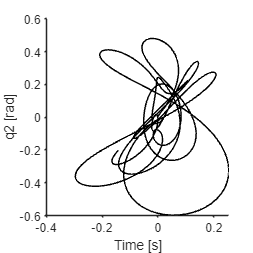

figure;
plot(Train.Pd(:,1), Train.Pd(:,2),'LineWidth',1,'color','#000000')

set(gca, 'Box', 'off', 'TickDir', 'out'); %,'XLim',[0, 250], 'YLim',[-1, 1.5]
set(gcf,'unit','centimeters','position',[0 0 10 10]);
xlabel('Time [s]');ylabel('q2 [rad]');

drawnow update;shg;

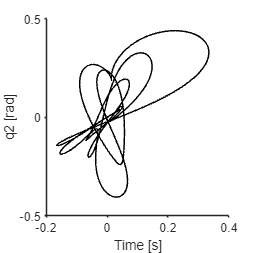

figure;
plot(Test_185s.Pd(:,1), Test_185s.Pd(:,2),'LineWidth',1,'color','#000000')

set(gca, 'Box', 'off', 'TickDir', 'out'); %,'XLim',[0, 250], 'YLim',[-1, 1.5]
set(gcf,'unit','centimeters','position',[0 0 10 10]);
xlabel('Time [s]');ylabel('q2 [rad]');

drawnow update;shg;

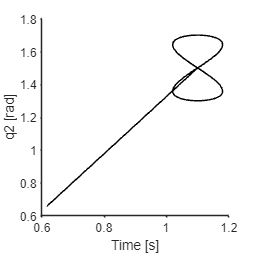

figure;
plot(Test_96s.Pd(:,1), Test_96s.Pd(:,3),'LineWidth',1,'color','#000000')

set(gca, 'Box', 'off', 'TickDir', 'out'); %,'XLim',[0, 250], 'YLim',[-1, 1.5]
set(gcf,'unit','centimeters','position',[0 0 10 10]);
xlabel('Time [s]');ylabel('q2 [rad]');

drawnow update;shg;